# **Progetto regolatore con luogo delle radici**

#### inizializzazione dell'ambiente

clear
close all
clc

#### Definizione della funzione di trasferimento tempo continuo del processo

% parameters
Tau_meca = 0.072;
Tau_sensore = 0.014;
Tau = Tau_sensore + Tau_meca;
T = 0.115;
mu = 1;

% G_ = G not delayed
G_ = tf(mu, [T 1 0]);

% G
G = G_;
G.IODelay = Tau

G =
 
                        1
  exp(-0.086*s) * -------------
                  0.115 s^2 + s
 
Continuous-time transfer function.



**Definizione della funzione di trasferimento tempo discreto del processo**

%discretizzazione di G
Tc = 0.02;
G_d = c2d(G, Tc)

G_d =
 
           0.0008186 z^2 + 0.00224 z + 0.0001339
  z^(-5) * -------------------------------------
                   z^2 - 1.84 z + 0.8404
 
Sample time: 0.02 seconds
Discrete-time transfer function.



G_d = tf([0.0008186 0.00224 0.0001339], [1 -1.84 0.8404 0 0 0 0 0], Tc) %riscritto in forma canonica

G_d =
 
  0.0008186 z^2 + 0.00224 z + 0.0001339
  -------------------------------------
       z^7 - 1.84 z^6 + 0.8404 z^5
 
Sample time: 0.02 seconds
Discrete-time transfer function.



**Traccio luogo delle radici di G_d**

% poli e zeri di G_d
[poliG_d, zeriG_d] = pzmap(G_d)

poliG_d =          0
         0
         0
         0
         0
    0.9975
    0.8425


zeriG_d =    -2.6752
   -0.0611


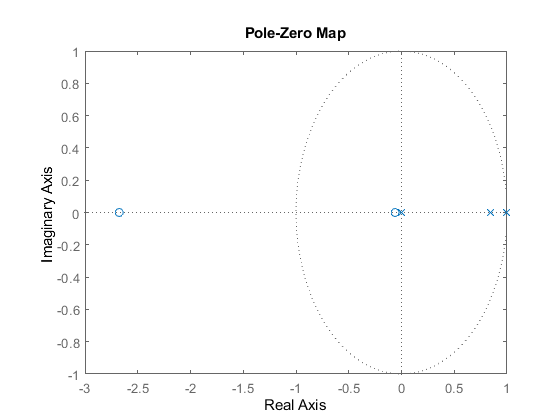

pzmap(G_d)

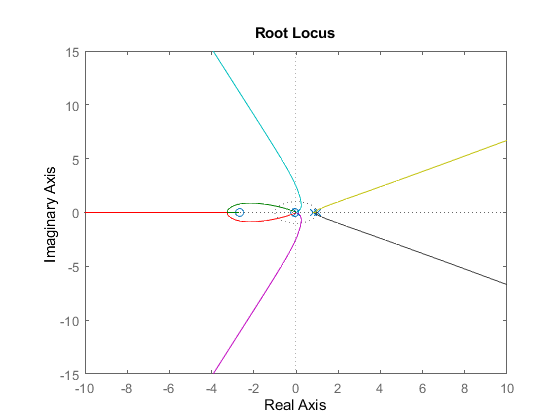


%traccio luogo
rlocus(G_d)

**Opero su luogo delle radici per trovare il regolatore**

% richieste per regolatore:

%  - asintotica stabilità del sistema ad anello chiuso
%  - astatismo a gradino 
%  - tempo assestamento < 0.5s

rltool(G_d, Tc)

% ho trovato la possibile soluzione

% - zero in 0.843
% - 2 poli in -0.477

**Dichiaro regolatore senza guadagno**

%R_no_gain = tf([-2.3 1], [1.883 1], Tc)
R_no_gain = tf(poly([0.843]), poly([-0.477 -0.477]), Tc)

R_no_gain =
 
        z - 0.843
  ----------------------
  z^2 + 0.954 z + 0.2275
 
Sample time: 0.02 seconds
Discrete-time transfer function.



**Trovo il guadagno desiderato per le mie specifiche**

%POSIZIONE DESIDERATA DEI POLI

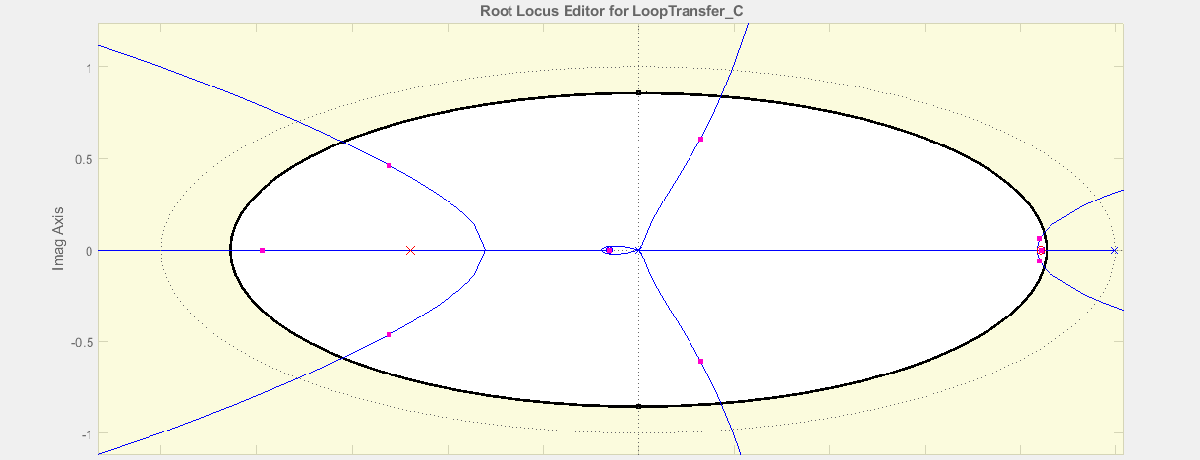

%traccio relazione poli a ciclo chiuso, guadagno d'anello
L_no_gain = G_d* R_no_gain; %open loop senza guadagno

k = (1:1:100);
r = rlocus(L_no_gain,k)

r =    0.9960 + 0.0000i   0.9945 + 0.0000i   0.9929 + 0.0000i   0.9914 + 0.0000i   0.9898 + 0.0000i   0.9882 + 0.0000i   0.9865 + 0.0000i   0.9848 + 0.0000i   0.9831 + 0.0000i   0.9814 + 0.0000i   0.9796 + 0.0000i   0.9778 + 0.0000i   0.9760 + 0.0000i   0.9741 + 0.0000i   0.9722 + 0.0000i   0.9702 + 0.0000i   0.9682 + 0.0000i   0.9661 + 0.0000i   0.9640 + 0.0000i   0.9619 + 0.0000i   0.9596 + 0.0000i   0.9573 + 0.0000i   0.9550 + 0.0000i   0.9526 + 0.0000i   0.9501 + 0.0000i   0.9475 + 0.0000i   0.9448 + 0.0000i   0.9420 + 0.0000i   0.9392 + 0.0000i   0.9362 + 0.0000i   0.9330 + 0.0000i   0.9298 + 0.0000i   0.9263 + 0.0000i   0.9227 + 0.0000i   0.9189 + 0.0000i   0.9148 + 0.0000i   0.9104 + 0.0000i   0.9057 + 0.0000i   0.9006 + 0.0000i   0.8949 + 0.0000i   0.8886 + 0.0000i   0.8815 + 0.0000i   0.8733 + 0.0000i   0.8645 + 0.0000i   0.8567 + 0.0000i   0.8519 + 0.0000i   0.8494 + 0.0000i   0.8479 + 0.0000i   0.8470 + 0.0000i   0.8463 + 0.0000i
   0.8425 + 0.0000i   0.8425 + 0.0000i   0.84


%our position of poles of interest is this column
display(r(:,47))        %index 47 is the nearest to the desired situation

   0.8494 + 0.0000i
   0.8355 + 0.0550i
  -0.7885 + 0.0000i
  -0.5215 + 0.4601i
  -0.5215 - 0.4601i
   0.8355 - 0.0550i
   0.1291 + 0.6045i
   0.1291 - 0.6045i
  -0.0611 + 0.0000i



display(k(47))

    47



%found mu
mu_R = k(47);

**Funzioni definitive**

R = mu_R * R_no_gain        %regolatore

R =
 
       47 z - 39.62
  ----------------------
  z^2 + 0.954 z + 0.2275
 
Sample time: 0.02 seconds
Discrete-time transfer function.



L = R * G_d                 %open loop function

L =
 
     0.03847 z^3 + 0.07285 z^2 - 0.08246 z - 0.005305
  ------------------------------------------------------
  z^9 - 0.886 z^8 - 0.6874 z^7 + 0.3831 z^6 + 0.1912 z^5
 
Sample time: 0.02 seconds
Discrete-time transfer function.



L_close = feedback(L, 1)    %close loop function

L_close =
 
                                                       
       0.03847 z^3 + 0.07285 z^2 - 0.08246 z - 0.005305
                                                       
  -----------------------------------------------------------
                                                             
  z^9 - 0.886 z^8 - 0.6874 z^7 + 0.3831 z^6 + 0.1912 z^5     
                                                             
           + 0.03847 z^3 + 0.07285 z^2 - 0.08246 z - 0.005305
                                                             
 
Sample time: 0.02 seconds
Discrete-time transfer function.



**Qualche test sulla funzione F**

F = L/(1+L)

F =
 
                                                             
  0.03847 z^12 + 0.03876 z^11 - 0.1734 z^10 + 0.03241 z^9    
                                                             
          + 0.09665 z^8 - 0.01401 z^7 - 0.0178 z^6           
                                                             
                                               - 0.001014 z^5
                                                             
  -----------------------------------------------------------
                                                             
  z^18 - 1.772 z^17 - 0.5899 z^16 + 1.984 z^15 + 0.1762 z^14 
                                                             
          - 0.8655 z^13 - 0.07766 z^12 + 0.1853 z^11         
                                                             
          - 0.1369 z^10 + 0.03241 z^9 + 0.09665 z^8          
                                                             
                    - 0.01401 z^7 - 0.0178 z^6 - 0.001014 z^5
  

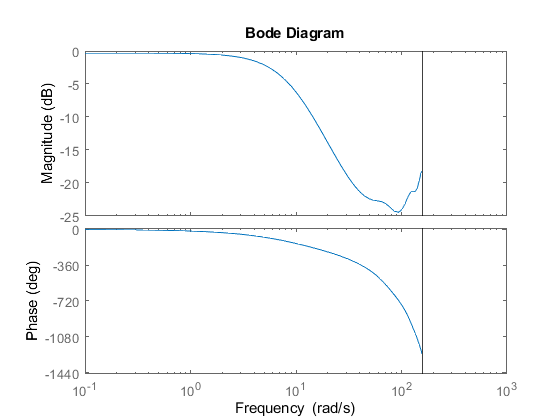

Q =
 
                                                               
    47 z^10 - 81.26 z^9 + 2.795 z^8 + 45.24 z^7 - 6.191 z^6    
                                                               
                                                    - 7.576 z^5
                                                               
  ---------------------------------------------------------------
                                                                 
  z^11 + 0.068 z^10 - 1.305 z^9 - 0.4743 z^8 + 0.4003 z^7        
                                                                 
          + 0.2696 z^6 + 0.08198 z^5 + 0.1096 z^4 - 0.004208 z^3 
                                                                 
                          - 0.0674 z^2 - 0.02382 z - 0.001207    
                                                                 
 
Sample time: 0.02 seconds
Discrete-time transfer function.



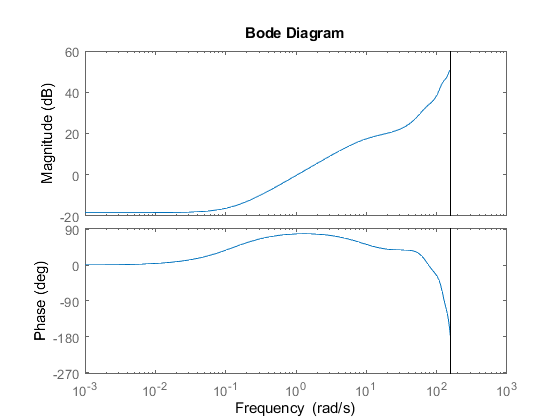


bode(F)

**Qualche test sulla funzione ad anello chiuso**

%TEST

%poles and zeros 
[poli, zeri] = pzmap(L_close)

poli =   -0.7885 + 0.0000i
  -0.5215 + 0.4601i
  -0.5215 - 0.4601i
   0.1291 + 0.6045i
   0.1291 - 0.6045i
   0.8355 + 0.0550i
   0.8355 - 0.0550i
   0.8494 + 0.0000i
  -0.0611 + 0.0000i


zeri =    -2.6752
    0.8430
   -0.0611


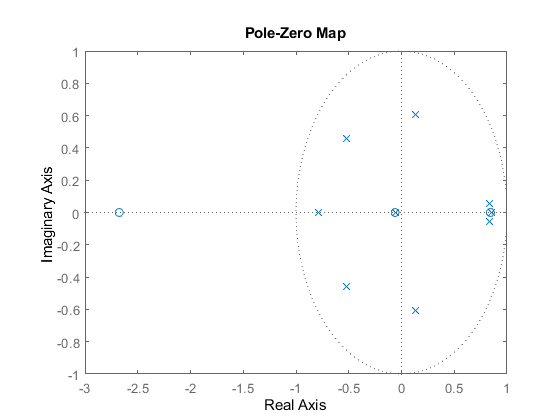

pzmap(L_close)

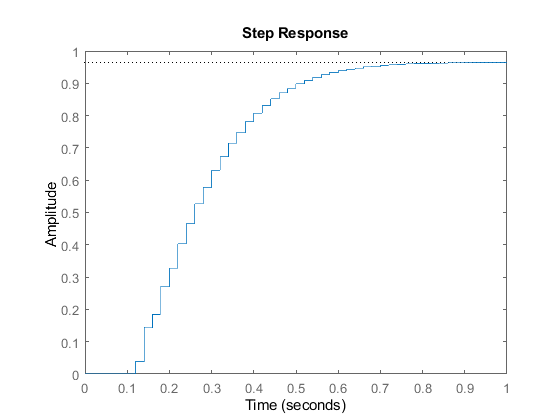



%indicial response
step(L_close)

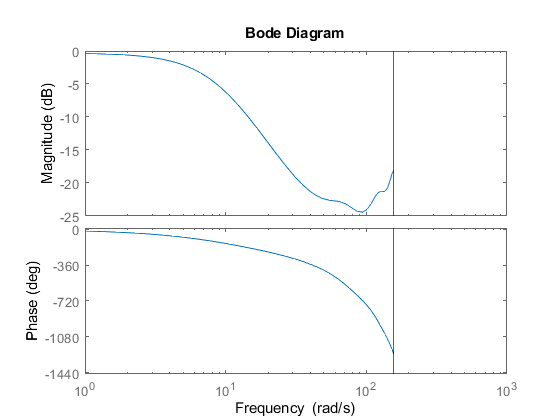



%bode diagram
bode(L_close)

**Analisi risultati:**

**R =      47z - 39.62**

**       -----------------------**

**      z^2 +0.954z +0.2275**

**Garantisce per il nostro sistema a ciclo chiuso:**

- **Stabilità**

- **Tempo di assestamento di circa 0.5s**

- **No sovraelongazione (considerazione su grafico risposta indiciale)**

**Inoltre grazie al polo in 1 di G_d, è garantita la seguente prestazione statica:**

- **astatismo al gradino**